# Project:  Pick and Place task using RRR robotic arm: 

## Name: Yazan Maalla     ISU: 345153

## Model description:

The robot consists of three links: the first link rotates around the z-axis expressed in the world frame, the second and the third links rotate around the x-axis expressed in the world frame. 

                                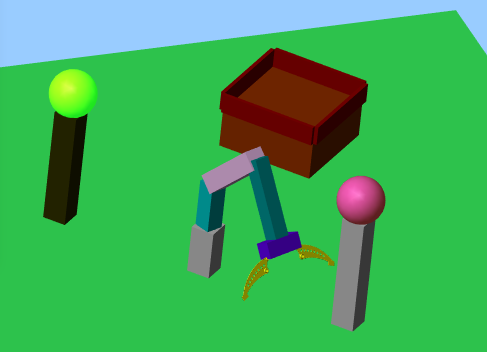

Our task: to pick two sphere_shaped objects, from different positions, and place them in the a desired position(here the box).

Initial Parameters:

l1 = 0.3; % lenght of the first link [m] 
l2 = 0.4; % length of the second link [m] 
l3 = 0.4; % length of the second link [m] 
m1 = 6; % the first link mass [kg] 
m2 = 5; % the second link mass [kg] 
m3 = 4; % the second link mass [kg]
StopTime = 30; % simulation time 
kk=5; b=0.01;
kp = 900; ki = 300; kd = 500; %  controller cooficients


% Desired trajectory 

traj=generateTrajectory();

p_des_x =cell2mat(traj(1));
p_des_y =cell2mat(traj(2));
p_des_z =cell2mat(traj(3));
dt=cell2mat(traj(4));
tt=cell2mat(traj(5));
time_values=cell2mat(traj(6));


#### Run the model

 project_345153 % to open the model 
 simOut = sim('project_345153'); % to runs 

##  Plots:

figure;
subplot(3,1,1);
plot(outputs1.p_des.time, outputs1.p_des.data(:,1),...
     outputs1.p_act.time, outputs1.p_act.data(:,1),'--', 'linewidth', 2);
grid on;
legend('$x_{des}$', '$x_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$x$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,2);
plot(outputs1.p_des.time, outputs1.p_des.data(:,2),...
     outputs1.p_act.time, outputs1.p_act.data(:,2),'--', 'linewidth', 2);
grid on;
legend('$y_{des}$', '$y_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$y$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,3);
plot(outputs1.p_des.time, outputs1.p_des.data(:,3),...
     outputs1.p_act.time, outputs1.p_act.data(:,3),'--', 'linewidth', 2);
grid on;
legend('$z_{des}$', '$z_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$z$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');



figure;
subplot(3,1,1);
plot(outputs1.p_des.time, outputs1.q_des.data(:,1),...
     outputs1.p_act.time, outputs1.q_act.data(:,1),'--', 'linewidth', 2);
grid on;
legend('$q1_{des}$', '$q1_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$q1$ [rad]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');

subplot(3,1,2);
plot(outputs1.p_des.time, outputs1.q_des.data(:,2),...
     outputs1.p_act.time, outputs1.q_act.data(:,2),'--', 'linewidth', 2);
grid on;
legend('$q2_{des}$', '$q2_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$q2$ [rad]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');


subplot(3,1,3);
plot(outputs1.p_des.time, outputs1.q_des.data(:,3),...
     outputs1.p_act.time, outputs1.q_act.data(:,3),'--', 'linewidth', 2);
grid on;
legend('$q2_{des}$', '$q2_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$q2$ [rad]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');


figure;
title('Joints torques');
plot(outputs1.tau.time, outputs1.tau.data(:,1),...
	 outputs1.tau.time, outputs1.tau.data(:,2),...
     outputs1.tau.time, outputs1.tau.data(:,3));
grid on;
legend('$\tau_1$', '$\tau_2$', '$\tau_3$', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
ylabel('$\tau$ [Nm]', 'fontsize',14,'interpreter','latex');



figure;
subplot(2,1,1);
title('Contact modeling 1st ball');
plot(outputs1.Normal.time, outputs1.Normal.data,...
     outputs1.Friction.time, outputs1.Friction.data);
grid on;
legend('$F_n$', '$F_f$', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
ylabel('$F$ [N]', 'fontsize',14,'interpreter','latex');
ylim([0 120]);

subplot(2,1,2);
title('Contact modeling 2nd ball');
plot(outputs1.Normal2.time, outputs1.Normal2.data,...
     outputs1.Friction.time, outputs1.Friction2.data);
grid on;
legend('$F_n$', '$F_f$', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
ylabel('$F$ [N]', 'fontsize',14,'interpreter','latex');
ylim([0 120]);